clear; clc; close all;

%% =================================================================
%% 1. INITIALIZE HARDWARE (CAMERA & ROBOT)
%% =================================================================
% --- Camera Setup ---
pipe = realsense.pipeline();
cfg = realsense.config();
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

pc = realsense.pointcloud();
align_to_color = realsense.align(realsense.stream.color);

% Transformation Matrix (Camera to World)
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065;
                   -0.9999    0.0103    0.0047    0.0586;
                   -0.0043    0.0408   -0.9992    0.7050;
                         0         0         0    1.0000];

% --- Robot Setup ---
port = 'COM5'; 
numServos = 5; 
try
    arb = Arbotix('port', port, 'nservos', numServos);
catch
    error('Failed to connect to robot.');
end

serPort COM5is in use.   Closing it.


i = 4


disp('Maximizing servo stiffness...');

Maximizing servo stiffness...


ADDR_CW_COMPLIANCE_MARGIN = 26;
ADDR_CCW_COMPLIANCE_MARGIN = 27;
arb.writedata1(1, ADDR_CW_COMPLIANCE_MARGIN, 2);
arb.writedata1(1, ADDR_CCW_COMPLIANCE_MARGIN, 2);
arb.writedata1(2, ADDR_CW_COMPLIANCE_MARGIN, 8);
arb.writedata1(2, ADDR_CCW_COMPLIANCE_MARGIN, 8);
pause(0.5); 

jaw_open_val  = 34; jaw_close_val = 27;
speed = 100;
pick_z_offset_mm = 50;  
place_z_offset_mm = 30; 

fprintf('Opening Jaw and Moving to Observation Pose...\n');

Opening Jaw and Moving to Observation Pose...


[~, th_open] = positionJaw(jaw_open_val);
arb.setpos(5, th_open, speed);
moveToCameraPose(arb, speed); 
pause(2);

% Start camera pipeline
profile = pipe.start(cfg);
disp('Camera warmed up and pipeline running.');

Camera warmed up and pipeline running.



%% =================================================================
%% 2. INITIAL ARUCO TRAY DETECTION (RUN ONCE)
%% =================================================================
% Flush buffer to get a clear image
for i = 1:10
    fs = pipe.wait_for_frames();
end
fs = align_to_color.process(fs);
color_frame = fs.get_color_frame();
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);

disp('Detecting ArUco Markers for Destination Trays...');

Detecting ArUco Markers for Destination Trays...


[markerIds, markerLocs] = readArucoMarker(I);

blue_bin_found = false; green_bin_found = false;
blue_pixel_x = 0; blue_pixel_y = 0; 
green_pixel_x = 0; green_pixel_y = 0;

depth_frame = fs.get_depth_frame();
pc.map_to(color_frame);
points = pc.calculate(depth_frame);
vtx = points.get_vertices();
valid_depth = (vtx(:,3) > 0);

if ~isempty(markerIds)
    for i = 1:length(markerIds)
        current_id = markerIds(i);
        corners = markerLocs(:,:,i);
        
        mask_2d = poly2mask(corners(:,1), corners(:,2), 480, 640);
        mask_1d = reshape(mask_2d', [], 1);
        bin_vtx = vtx(valid_depth & mask_1d, :);
        
        if ~isempty(bin_vtx)
            bin_pos_cam = mean(bin_vtx, 1);
            bin_pos_world_homog = T_world_camera * [bin_pos_cam, 1]';
            
            if current_id == 0
                blue_place_x = bin_pos_world_homog(1) * 1000;
                blue_place_y = bin_pos_world_homog(2) * 1000;
                blue_pixel_x = mean(corners(:,1));
                blue_pixel_y = mean(corners(:,2));
                blue_bin_found = true;
                fprintf('Blue Tray Detected at X: %.1f mm, Y: %.1f mm\n', blue_place_x, blue_place_y);
            elseif current_id == 2
                green_place_x = bin_pos_world_homog(1) * 1000;
                green_place_y = bin_pos_world_homog(2) * 1000;
                green_pixel_x = mean(corners(:,1));
                green_pixel_y = mean(corners(:,2));
                green_bin_found = true;
                fprintf('Green Tray Detected at X: %.1f mm, Y: %.1f mm\n', green_place_x, green_place_y);
            end
        end
    end
end

Blue Tray Detected at X: -185.5 mm, Y: -3.9 mm


Green Tray Detected at X: 23.7 mm, Y: 140.4 mm


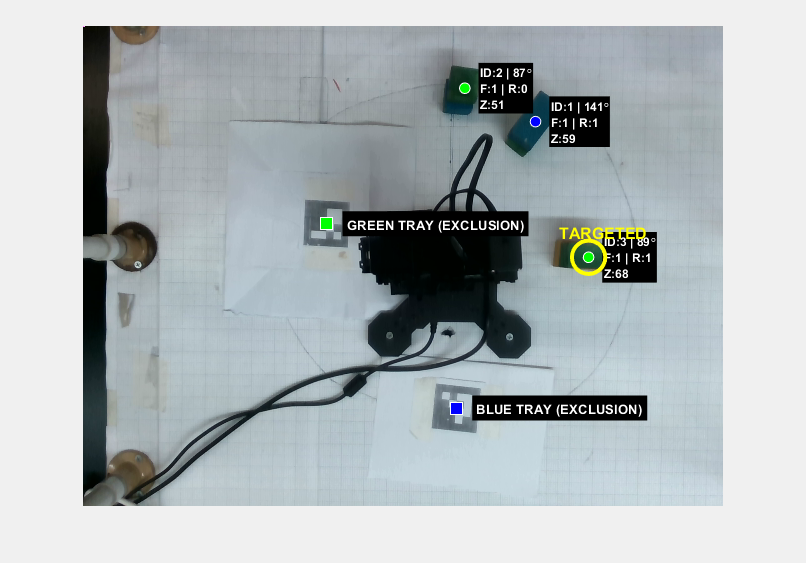

ITERATION 1: SCANNING WORKSPACE...


Initial Scan Complete. Waiting for you to click "START ROBOT" on the image window...


Proceeding to autonomous unstacking sequence...


Selecting Highest Target: Green Rectangle at Z: 67.7 mm


ITERATION 2: SCANNING WORKSPACE...


Selecting Highest Target: Blue Rectangle at Z: 56.5 mm


ITERATION 3: SCANNING WORKSPACE...


Selecting Highest Target: Green Square at Z: 48.5 mm


ITERATION 4: SCANNING WORKSPACE...


Selecting Highest Target: Green Rectangle at Z: 23.1 mm


ITERATION 5: SCANNING WORKSPACE...


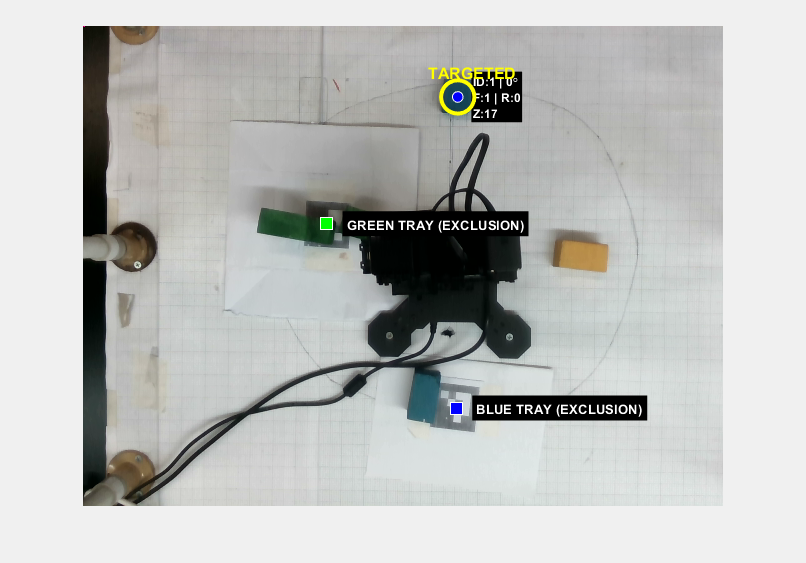

Selecting Highest Target: Blue Square at Z: 16.7 mm


ITERATION 6: SCANNING WORKSPACE...



No valid targets detected outside exclusion zones. Workspace cleared!



if ~blue_bin_found
    blue_place_x = 160; blue_place_y = 50; 
    disp('Blue Tray defaulted.');
end
if ~green_bin_found
    green_place_x = 160; green_place_y = -50; 
    disp('Green Tray defaulted.');
end

%% =================================================================
%% 3. CONTINUOUS PERCEPTION LOOP (TASK 4 CORE)
%% =================================================================
% Left/Right Split Placement Variables
y_split_offset = 35; 
blue_count = 0; green_count = 0;

% --- NEW: Base heights updated to 45mm ---
blue_floor_z = 40; 
green_floor_z = 40;

blue_stack_left_z = blue_floor_z; blue_stack_right_z = blue_floor_z;
green_stack_left_z = green_floor_z; green_stack_right_z = green_floor_z;

exclusion_radius_mm = 85; 
jaw_tolerance_deg = 12.5;

[U, V] = meshgrid(1:640, 1:480); 
U_1d = reshape(U', [], 1);
V_1d = reshape(V', [], 1);

f = figure('Name', 'Workspace Target Debug', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);
iteration = 1;

while true
    fprintf('\n=======================================================\n');
    fprintf('ITERATION %d: SCANNING WORKSPACE...\n', iteration);
    
    % Flush buffer
    for i = 1:10
        fs = pipe.wait_for_frames();
    end
    fs = align_to_color.process(fs);
    depth_frame = fs.get_depth_frame();
    color_frame = fs.get_color_frame();
    
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    vtx = points.get_vertices(); 
    valid_depth = (vtx(:,3) > 0);
    
    color_data = color_frame.get_data();
    I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);
    hsvI = rgb2hsv(I);
    H = hsvI(:,:,1); S = hsvI(:,:,2); V = hsvI(:,:,3);
    
    % Segment Colors
    hueMask_B = (H > 0.52) & (H < 0.65); 
    level_B = max(graythresh(S), 0.40); 
    mask_blue = bwareaopen(imfill(hueMask_B & (S > level_B) & (V > 0.25), 'holes'), 100);

    H_MIN_GREEN = 0.232; H_MAX_GREEN = 0.490;
    S_MIN_GREEN = 0.292; S_MAX_GREEN = 1.000;
    V_MIN_GREEN = 0.138; V_MAX_GREEN = 0.579;
    mask_green = bwareaopen(imfill((H >= H_MIN_GREEN) & (H <= H_MAX_GREEN) & ...
                (S >= S_MIN_GREEN) & (S <= S_MAX_GREEN) & ...
                (V >= V_MIN_GREEN) & (V <= V_MAX_GREEN), 'holes'), 100);
    
    % Extract Targets
    blue_targets = get_targets(mask_blue, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, 'Blue', U_1d, V_1d);
    green_targets = get_targets(mask_green, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, 'Green', U_1d, V_1d);
    
    raw_targets = [blue_targets, green_targets];
    
    % Spatial Exclusion Filter
    all_targets = [];
    current_id = 1;
    for i = 1:length(raw_targets)
        t_x = raw_targets(i).pos(1) * 1000;
        t_y = raw_targets(i).pos(2) * 1000;
        
        dist_to_blue = sqrt((t_x - blue_place_x)^2 + (t_y - blue_place_y)^2);
        dist_to_green = sqrt((t_x - green_place_x)^2 + (t_y - green_place_y)^2);
        
        if dist_to_blue > exclusion_radius_mm && dist_to_green > exclusion_radius_mm
            raw_targets(i).id = current_id; 
            current_id = current_id + 1;
            all_targets = [all_targets, raw_targets(i)];
        end
    end
    
    if isempty(all_targets)
        fprintf('\nNo valid targets detected outside exclusion zones. Workspace cleared!\n');
        break;
    end
    
    % Sort by Height (Z descending) to unstack properly
    z_vals = arrayfun(@(t) t.pos(3), all_targets);
    [~, sort_idx] = sort(z_vals, 'descend');
    all_targets = all_targets(sort_idx);
    
    target_to_pick = [];
    for i = 1:length(all_targets)
        if all_targets(i).feasible
            target_to_pick = all_targets(i);
            break; 
        end
    end
    
    if isempty(target_to_pick)
        fprintf('\nTargets visible, but none are feasible to grasp. Stopping.\n');
        break;
    end

    % DYNAMIC VISUALIZATION
    figure(f); imshow(I); hold on;

    if blue_bin_found
        plot(blue_pixel_x, blue_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'b');
        text(blue_pixel_x + 20, blue_pixel_y, 'BLUE TRAY (EXCLUSION)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
    end
    if green_bin_found
        plot(green_pixel_x, green_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'g');
        text(green_pixel_x + 20, green_pixel_y, 'GREEN TRAY (EXCLUSION)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
    end

    for i = 1:length(all_targets)
        t = all_targets(i);
        marker_color = 'b'; if strcmp(t.color, 'Green'), marker_color = 'g'; end
        text_bg = 'k'; if ~t.feasible, text_bg = 'r'; end
        
        plot(t.pixel_x, t.pixel_y, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', marker_color);
        annot_str = sprintf('ID:%d | %d\\circ\nF:%d | R:%d\nZ:%.0f', t.id, round(t.angle), t.feasible, t.is_rect, t.pos(3)*1000);
        text(t.pixel_x + 15, t.pixel_y, annot_str, 'Color', 'w', 'BackgroundColor', text_bg, 'FontSize', 9, 'FontWeight', 'bold', 'Margin', 1);
        
        if t.id == target_to_pick.id
            plot(t.pixel_x, t.pixel_y, 'o', 'MarkerSize', 25, 'MarkerEdgeColor', 'y', 'LineWidth', 3);
            text(t.pixel_x - 30, t.pixel_y - 25, 'TARGETED', 'Color', 'y', 'FontWeight', 'bold', 'FontSize', 12);
        end
    end
    hold off;

    if iteration == 1
        btn = uicontrol(f, 'Style', 'pushbutton', 'String', 'START ROBOT', 'Position', [20, 20, 150, 50], ...
            'FontSize', 12, 'FontWeight', 'bold', 'BackgroundColor', 'g', 'Callback', 'uiresume(gcbf)');
        disp('Initial Scan Complete. Waiting for you to click "START ROBOT" on the image window...');
        drawnow limitrate; shg; uiwait(f);
        if isvalid(btn), delete(btn); end
        disp('Proceeding to autonomous unstacking sequence...'); drawnow; 
    else
        drawnow limitrate; pause(1); 
    end

    % Execution
    t = target_to_pick;
    shape_str = 'Square'; if t.is_rect, shape_str = 'Rectangle'; end
    fprintf('Selecting Highest Target: %s %s at Z: %.1f mm\n', t.color, shape_str, t.pos(3)*1000);
    
    pick_x = t.pos(1) * 1000;
    pick_y = t.pos(2) * 1000;
    pick_z = t.pos(3) * 1000; 
    
    % --- NEW: Hardcoded physical thickness of the blocks ---
    cube_thickness = 35; % Adjust this value to the exact mm thickness of your cubes if needed
    
    pick  = [pick_x, pick_y, pick_z, deg2rad(175)];  
    
    % Split Tray Logic
    if strcmp(t.color, 'Blue')
        is_left_side = (mod(blue_count, 2) == 0); 
        if is_left_side
            target_place_y = blue_place_y + y_split_offset;
            current_place_z = blue_stack_left_z; 
            blue_stack_left_z = current_place_z + cube_thickness; % Set up next height
        else
            target_place_y = blue_place_y - y_split_offset;
            current_place_z = blue_stack_right_z;
            blue_stack_right_z = current_place_z + cube_thickness; 
        end
        target_place_x = blue_place_x;
        blue_count = blue_count + 1;
    else 
        is_left_side = (mod(green_count, 2) == 0);
        if is_left_side
            target_place_y = green_place_y + y_split_offset;
            current_place_z = green_stack_left_z;
            green_stack_left_z = current_place_z + cube_thickness; 
        else
            target_place_y = green_place_y - y_split_offset;
            current_place_z = green_stack_right_z;
            green_stack_right_z = current_place_z + cube_thickness; 
        end
        target_place_x = green_place_x;
        green_count = green_count + 1;
    end

    place = [target_place_x, target_place_y, current_place_z, deg2rad(175)];
    pre_pick  = pick  + [0, 0, pick_z_offset_mm, 0];
    pre_place = place + [0, 0, place_z_offset_mm, 0];
    
    try
        % Pick
        moveRobotToTarget(arb, pre_pick, speed, 2); 
        moveRobotToTarget(arb, pick, speed, 2);     
        [~, th_close] = positionJaw(jaw_close_val);
        arb.setpos(5, th_close, speed); pause(2);
        
        % % Retract & Go to Observation Pose
        % moveRobotToTarget(arb, pre_pick, speed, 2);  
        % moveToCameraPose(arb, speed);
        for j = 2:4, arb.setpos(j, 0, speed); end % Safe home
        pause(1); arb.setpos(1, 0, speed); pause(1);
        
        % Place
        moveRobotToTarget(arb, pre_place, speed, 2); 
        moveRobotToTarget(arb, place, speed, 2);     
        arb.setpos(5, th_open, speed); pause(1); 
        
        % Retract & Go to Observation Pose
        moveRobotToTarget(arb, pre_place, speed, 2);  
        moveToCameraPose(arb, speed); 
        pause(2)
        
    catch ME
        fprintf('--> ERROR during movement: %s\n', ME.message);
        arb.setpos(5, th_open, speed);
        moveToCameraPose(arb, speed);
    end
    
    iteration = iteration + 1;
end


pipe.stop();
fprintf('\nTask 4 Sequence Finished.\n');


Task 4 Sequence Finished.



%% =================================================================
%% LOCAL HELPER FUNCTIONS
%% =================================================================
function moveToCameraPose(arb, speed)
    cam_pose = [1.5902	-0.2506	2.3777	1.2067];
    for i = 1:4
        arb.setpos(i, cam_pose(i), speed);
    end
    pause(2); 
end

function targets = get_targets(mask, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, color_name, U_1d, V_1d)
    targets = [];
    mask_1d = reshape(mask', [], 1);
    indices = valid_depth & mask_1d;
    cluster_vtx = vtx(indices, :);

    if isempty(cluster_vtx)
        return;
    end

    ptCloud = pointCloud(cluster_vtx);
    [labels, numClusters] = pcsegdist(ptCloud, 0.008);

    for c = 1:numClusters
        cubeIndices = find(labels == c);
        if length(cubeIndices) < 150
            continue;
        end

        cubeCloud = select(ptCloud, cubeIndices);
        
        pos_cam = mean(cubeCloud.Location, 1);
        pos_world_homog = T_world_camera * [pos_cam, 1]';
        curr_pos_world = pos_world_homog(1:3)';

        points_cam_homog = [cubeCloud.Location, ones(size(cubeCloud.Location, 1), 1)]'; 
        points_world = (T_world_camera * points_cam_homog)'; 

        max_z = max(points_world(:, 3)); 
        top_face_indices = points_world(:, 3) > (max_z - 0.005);
        top_points_xy = points_world(top_face_indices, 1:2); 

        search_angles = 0:1:89;
        areas = zeros(size(search_angles));
        box_widths = zeros(size(search_angles));
        box_heights = zeros(size(search_angles));

        for a_idx = 1:length(search_angles)
            t_ang = deg2rad(search_angles(a_idx));
            u = [cos(t_ang); sin(t_ang)];
            v = [-sin(t_ang); cos(t_ang)];
            
            proj_u = top_points_xy * u;
            proj_v = top_points_xy * v;
            
            w = max(proj_u) - min(proj_u);
            h = max(proj_v) - min(proj_v);
            
            areas(a_idx) = w * h;
            box_widths(a_idx) = w;
            box_heights(a_idx) = h;
        end

        [~, min_idx] = min(areas);
        best_angle_deg = search_angles(min_idx);
        final_w = box_widths(min_idx);
        final_h = box_heights(min_idx);

        aspect_ratio = max(final_w, final_h) / min(final_w, final_h);
        is_rect = false;
        curr_angle_deg = best_angle_deg;

        if aspect_ratio > 1.3 
            is_rect = true;
            if final_h > final_w
                curr_angle_deg = mod(best_angle_deg + 90, 180);
            end
        end

        theta_arm_deg = rad2deg(atan2(curr_pos_world(2), curr_pos_world(1)));
        angular_diff = curr_angle_deg - theta_arm_deg;
        
        if is_rect
            curr_angular_error = abs(mod(angular_diff + 90, 180) - 90);
        else
            curr_angular_error = abs(mod(angular_diff + 45, 90) - 45);
        end
        is_feasible = (curr_angular_error <= jaw_tolerance_deg);
        
        local_idx = find(labels == c);
        global_indices = find(indices);
        cluster_global_idx = global_indices(local_idx);

        cols = U_1d(cluster_global_idx);
        rows = V_1d(cluster_global_idx);
        pixel_x_target = mean(cols);
        pixel_y_target = mean(rows);

        new_target.color = color_name;
        new_target.pos = curr_pos_world;
        new_target.angle = curr_angle_deg;
        new_target.error = curr_angular_error;
        new_target.feasible = is_feasible;
        new_target.is_rect = is_rect;
        new_target.pixel_x = pixel_x_target;
        new_target.pixel_y = pixel_y_target;
        
        targets = [targets, new_target];
    end
end

function moveRobotToTarget(arb, target, speed, pause_time)

    fullConfig = zeros(1, 4);
    for i = 1:4
        pos = arb.getpos(i);
        if ~isempty(pos)
            fullConfig(i) = pos;
        end
    end
    
    % --- THE COMBINED FRAME CALIBRATION ---
    dx = 7.896;  
    dy = -0.885;  
    x_shifted = target(1) + dx;
    y_shifted = target(2) + dy;
    
    angle_offset_deg =-1.104; %-1.944; 
    theta = deg2rad(angle_offset_deg);
    
    x_corrected = x_shifted * cos(theta) - y_shifted * sin(theta);
    y_corrected = x_shifted * sin(theta) + y_shifted * cos(theta);
    
    % ==========================================
    % PURE MATH DYNAMIC PHI 
    % ==========================================
    theta1_ideal_deg = rad2deg(atan2(y_corrected, x_corrected));
    
    if theta1_ideal_deg > -45 && theta1_ideal_deg <= 135
        dynamic_phi_deg = 175;    
    else
        dynamic_phi_deg = 185;
    end
    
    radius = sqrt(x_corrected^2 + y_corrected^2);
    if radius > 185
        dynamic_phi_deg = 180; 
    end
    
    dynamic_phi = deg2rad(dynamic_phi_deg);

    solutions = findSolution(x_corrected, y_corrected, target(3), dynamic_phi, fullConfig);
    
    if isempty(solutions)
        error('IK Solver failed: No valid joint angles found for this target.');
    end
    
    for joint = 1:4
        arb.setpos(joint, solutions(joint), speed);
    end
    pause(pause_time);
end
